Write the loop closer equations here.

/*

*/

% angular velocities in anticlockwise are taken positive.
% velocities in +x direction (right) are poistive else negative.
T; 
%[t2;t3;t4;t5;t6]
L;
%L=[O2A AC AB CB CD DO6 O2B O2O6];
O2A=L(1);
AC=L(2);
AB=L(3);
CB=L(4);
CD=L(5);
DO6=L(6);
O2B=L(7);
O2O6=L(8);

tB=22.3316450092*pi/180; %Angle at ABC in triangle (i.e angle at B)
a2=2; %alpha 2 in rad/s^2.


$$\omega_2=\sqrt{2\cdot\theta_2\cdot\alpha_2$$


w2=sqrt((2*a2).*T(1,:));


$$\omega_3=\frac{O_2A\cdot\cos(\theta_2)\cdot\omega_2}{AB\cdot\cos(\theta_3+\angle{ABC)}}

\$$



$$V_4=-O_2A\cdot\sin(\theta_2)\cdot\omega_2+AB\cdot\sin(\theta_3+\angle{ABC})\cdot\omega_3$$


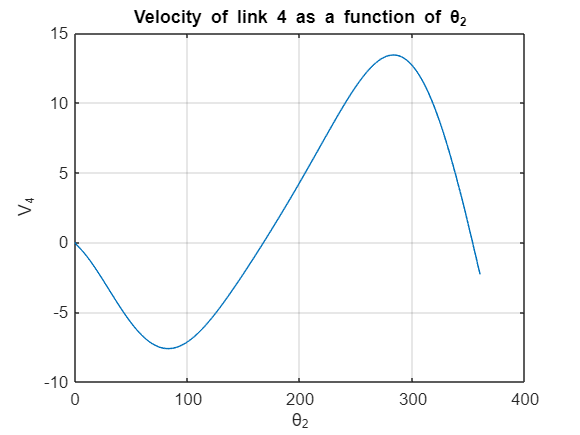

w3=(O2A.*(cos(T(1,:)).*w2))./(AB.*cos(T(2,:)+tB));

%velocity of link 4.

V4=-O2A.*(sin(T(1,:)).*w2)+AB.*(sin(T(2,:)+tB).*w3);

%********plot for velocity of link 4*********
figure
plot(T(1,:)*180/pi,V4)
xlabel('\theta_2')
ylabel('V_4')
title('Velocity of link 4 as a function of \theta_2')
grid on

w4 is the angular velocity of AC w.r.t to ground 

which is same as w3, because w3 is angular velocity of BC w.r.t ground as both

AC and BC are part of same rigid body w4=w3

or we use analytic method to solve w4

either way the answer is same.


$$\omega_4=\frac{CB\cdot\cos(\theta_3)\cdot\omega_3-O_2A\cdot\cos(\theta_2)\cdot\omega_2}{AC\cdot\cos(\theta_4)}$$


w4=( CB.*(cos(T(2,:)).*w3)-O2A.*(cos(T(1,:)).*w2) )./(AC.*cos(T(3,:)));


$$\pmatrix{CD\cdot\cos(\theta_5) & -O_6D\cdot\cos(\theta_6) \cr -CD\cdot\sin(\theta_5) & O_6D\cdot\sin(\theta_6)}\cdot\pmatrix{\omega_5 \cr \omega_6}=\pmatrix{-CB\cdot\cos(\theta_3)\cr O_2A\sin(\theta_2)\omega_2+AC\cdot\sin(\theta_4)\cdot\omega_4}$$


solve_for_w5_w6() function solves this matrix and gives the results w5,w6.

[w5,w6]=solve_for_w5_w6(L,T,w2,w3,w4);

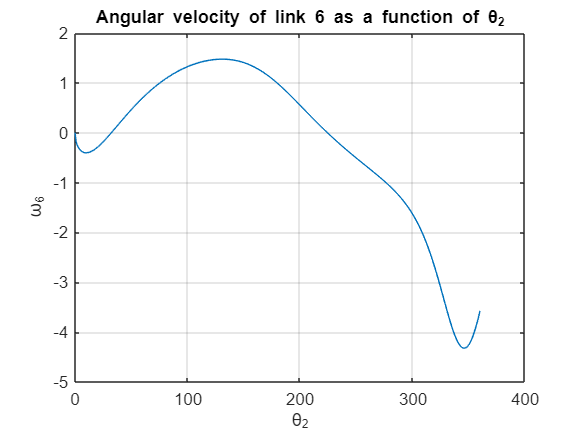

%%**********plot for angular velocity of link 6*****
figure
plot(T(1,:)*180/pi,w6)
xlabel('\theta_2')
ylabel('\omega_6')
title('Angular velocity of link 6 as a function of \theta_2')
grid on


clearvars -except T L w2 w3 w4 w5 w6 tB